# Classic CHIMERA Models (SIR)

## **Model (1)**

with $\phi(t)$ probaiblity:

## 
$$R_T$$
 

**1. **Define the conditions for all parameters and states of the model.

% clear; clc; close all;
load("Results/Estimations_India_lsqc_simple.mat")
Index = 4155;

syms H_s H_i H_r N
syms mu_h gamma z

assume(H_s > 0)
assume(H_i > 0)
assume(H_r > 0)
assume(z > 0)
assume(gamma >= 0)
assume(mu_h <= 1)
assumeAlso(0 <= mu_h)

**2.** Create the transition and fertility expressions for the model.

N = H_s + H_r + H_i;
phi = ( 1 - 1/H_s) ^ (z * H_i * (H_s/N));

f1 = H_s * (1 - phi) * (1 - mu_h)

$$f1 = H_{s}\,\left({\left(1-\frac{1}{H_{s}}\right)}^{\frac{H_{i}\,H_{s}\,z}{H_{i}+H_{r}+H_{s}}}-1\right)\,\left(\mu_{h}-1\right)$$

t1 = H_i * (1 - exp(-gamma)) * (1 - mu_h)

$$t1 = H_{i}\,\left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)$$

**3. **Derivate the corresponding expressions

JF = diff(f1,H_i)

$$JF = H_{s}\,\log\left(1-\frac{1}{H_{s}}\right)\,{\left(1-\frac{1}{H_{s}}\right)}^{\frac{H_{i}\,H_{s}\,z}{H_{i}+H_{r}+H_{s}}}\,\left(\frac{H_{s}\,z}{H_{i}+H_{r}+H_{s}}-\frac{H_{i}\,H_{s}\,z}{{\left(H_{i}+H_{r}+H_{s}\right)}^{2}}\right)\,\left(\mu_{h}-1\right)$$

JT = diff(t1,H_i)

$$JT = \left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)$$

**4. **Calculate the $R_T$ expression

Rt = JF/(1-JT)

$$Rt = -\frac{H_{s}\,\log\left(1-\frac{1}{H_{s}}\right)\,{\left(1-\frac{1}{H_{s}}\right)}^{\frac{H_{i}\,H_{s}\,z}{H_{i}+H_{r}+H_{s}}}\,\left(\frac{H_{s}\,z}{H_{i}+H_{r}+H_{s}}-\frac{H_{i}\,H_{s}\,z}{{\left(H_{i}+H_{r}+H_{s}\right)}^{2}}\right)\,\left(\mu_{h}-1\right)}{\left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)-1}$$

## 
$$R_0$$


**1. **Define the conditions for all parameters and states of the model.

syms H_s H_i H_r N
syms mu_h gamma z

assume(H_s>0)
assume(H_i>0)
assume(H_r>0)
assume(z>0)
assume(gamma>=0)
assume(mu_h<=1)
assumeAlso(0<=mu_h)

**2. **Definition of the model equations

N = H_s + H_r + H_i;
phi = (1 - 1/H_s) ^ (z * H_i * (H_s/N));

f1 = H_s*(1 - mu_h)*phi + mu_h*N;
f2 = H_s*(1 - mu_h)*(1 - phi) + H_i*(1 - exp(-gamma))*(1 - mu_h);
f3 = H_r*(1 - mu_h) + H_i*exp(-gamma)*(1 - mu_h);

**3. **Obtein the disease-free equilibrium

dfe = simplify(subs([f1,f2,f3],{H_i,H_r},{0,0}))

$$dfe = \left(\begin{array}{ccc} H_{s} & 0 & 0 \end{array}\right)$$

**4. **Evaluate the equilibrium into $R_T$ expression to obtain $R_0$

R_0 = subs(Rt, {H_s, H_i, H_r}, dfe)

$$R\_0 = -\frac{H_{s}\,z\,\log\left(1-\frac{1}{H_{s}}\right)\,\left(\mu_{h}-1\right)}{\left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)-1}$$

## Equilibriums 

**1. **Define the conditions for all parameters and states of the model.

% clear;clc;close all
syms H_s H_i H_r N
syms  mu_h z gamma

assume(N >= 1)
assume(H_s>1)
assume(H_i>=0)
assume(H_r>=0)

assume(z >= 1)
assume(mu_h>0)
assumeAlso(mu_h<1)

**2.** Solve $H_r$ in terms of $H_i$ using $f_R$ 

H_r = H_i*gamma*(1 - mu_h)/mu_h

$$H\_r = -\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}$$

**3. Express the **$\psi(t)$ probaiblity in terms of $H_i$ and $N$. 

Starting with the exponent $\alpha = zH_i\frac{H_s}{N}$

psi = (1 - H_i/N)^z;

 **5.**  Using  $f_S$ expression  in $\phi(t)$, we have that $H_s$ is

 H_s = simplify(mu_h*N/(((1 - psi*(1 - mu_h)))))

$$H\_s = \frac{N\,\mu_{h}}{{\left(1-\frac{H_{i}}{N}\right)}^{z}\,\left(\mu_{h}-1\right)+1}$$

** 6. **Finally, implementing the algebraic restriction, we can solve the following expression to obtain the equilibriums.

func = H_s + H_i + H_r - N;
funcAux = func == 0

$$funcAux = H_{i}-N+\frac{N\,\mu_{h}}{{\left(1-\frac{H_{i}}{N}\right)}^{z}\,\left(\mu_{h}-1\right)+1}-\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}=0$$

**Example for calculating equilibrium points**

**1. **Evaluate the parameter values into the expression

func = subs(func,{gamma,mu_h,z,N},{exp(-Parameters(2,Index)),...
    Parameters(3,Index),Parameters(4,Index),33336563.4676})

$$func = \frac{1019266102197812851985063312939011\,H_{i}}{21239024072016547541139717095424}-\frac{2637639917309074894982649608823}{38685626227668133590597632\,\left(\frac{143820437406539363\,{\left(1-\frac{268435456\,H_{i}}{8948715615898147}\right)}^{1238071003057325/4503599627370496}}{144115188075855872}-1\right)}-\frac{8948715615898147}{268435456}$$

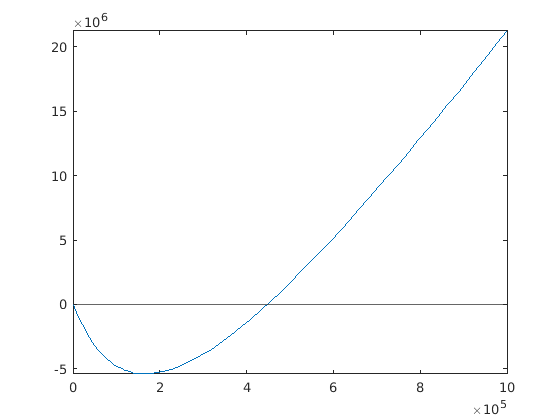

fplot(func,[0,1e6])
% ylim([-10 10])
yline(0)

**2. **Use a numerical method to obtain the corresponding equilibrium values.

sI = vpasolve(func == 0, H_i, 1e19)

$$sI = 447340.83945018855302444559662329$$

sR = subs(H_r, {gamma, mu_h, H_i}, {exp(-Parameters(2,Index)),...
    Parameters(3,Index), sI})

$$sR = 21020658.454408139640774804560583$$

sS = 33336563.4676-sI-sR

$$sS = 11868564.173741670965775258509786$$

## **Model (2)**

 with $\psi(t)$ probaiblity:

## 
$$R_T$$
 

**1. **Define the conditions for all parameters and states of the model.

% clear; clc; close all;
load("Results/Estimations_India_lsqc_complex.mat")
Index = 3904;

syms H_s H_i H_r N
syms mu_h gamma z

assume(H_s > 0)
assume(H_i > 0)
assume(H_r > 0)
assume(z >= 1)
assume(gamma >= 0)
assume(mu_h <= 1)
assumeAlso(0 <= mu_h)

**2.** Create the transition and fertility expressions for the model.

N = H_s + H_r + H_i;
psi = (1 - H_i/N)^z;

f1 = H_s * (1 - psi) * (1 - mu_h)

$$f1 = H_{s}\,\left(\mu_{h}-1\right)\,\left({\left(1-\frac{H_{i}}{H_{i}+H_{r}+H_{s}}\right)}^{z}-1\right)$$

t1 = H_i * (1 - exp(-gamma)) * (1 - mu_h)

$$t1 = H_{i}\,\left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)$$

**3. **Derivate the corresponding expressions

JF = diff(f1,H_i)

$$JF = H_{s}\,z\,\left(\frac{H_{i}}{{\left(H_{i}+H_{r}+H_{s}\right)}^{2}}-\frac{1}{H_{i}+H_{r}+H_{s}}\right)\,{\left(1-\frac{H_{i}}{H_{i}+H_{r}+H_{s}}\right)}^{z-1}\,\left(\mu_{h}-1\right)$$

JT = diff(t1,H_i)

$$JT = \left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)$$

**4. **Calculate the $R_T$ expression

Rt = JF/(1-JT)

$$Rt = -\frac{H_{s}\,z\,\left(\frac{H_{i}}{{\left(H_{i}+H_{r}+H_{s}\right)}^{2}}-\frac{1}{H_{i}+H_{r}+H_{s}}\right)\,{\left(1-\frac{H_{i}}{H_{i}+H_{r}+H_{s}}\right)}^{z-1}\,\left(\mu_{h}-1\right)}{\left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)-1}$$

## 
$$R_0$$


**1. **Define the conditions for all parameters and states of the model.

syms H_s H_i H_r N
syms mu_h gamma z

assume(H_s > 0)
assume(H_i > 0)
assume(H_r > 0)
assume(z > 1)
assume(gamma >= 0)
assume(mu_h <= 1)
assumeAlso(0 <= mu_h)

**2. **Definition of the model equations

N = H_s + H_r + H_i;
psi = (1 - H_i/N)^z;

f1 = H_s*(1 - mu_h)*(psi) + mu_h*N;
f2 = H_s*(1 - mu_h)*(1-psi) + H_i*(1 - exp(-gamma))*(1 - mu_h);
f3 = H_r*(1 - mu_h) + H_i*exp(-gamma)*(1 - mu_h);

**3. **Obtein the disease-free equilibrium

dfe = simplify(subs([f1,f2,f3], {H_i,H_r}, {0,0}))

$$dfe = \left(\begin{array}{ccc} H_{s} & 0 & 0 \end{array}\right)$$

**4. **Evaluate the equilibrium into $R_T$ expression to obtain $R_0$

R_0 = simplify(subs(Rt, {H_s, H_i, H_r}, dfe))

$$R\_0 = \frac{z\,\left(\mu_{h}-1\right)}{\left({\mathrm{e}}^{-\gamma }-1\right)\,\left(\mu_{h}-1\right)-1}$$

## Equilibriums 

**1. **Define the conditions for all parameters and states of the model.

% clear;clc;close all
syms H_s H_i H_r N
syms  mu_h z gamma

assume(N>=1)
assume(H_s>1)
assume(H_i>=0)
assume(H_r>=0)

assume(z>0)
assume(mu_h>0)
assumeAlso(mu_h<1)
% assume(gamma>0)

**2.** Solve $H_r$ in terms of $H_i$ using $f_R$ 

H_r = H_i*gamma*(1 - mu_h)/mu_h

$$H\_r = -\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}$$

**3. Express the **$\phi(t)$ probaiblity in terms of $H_i$ and $N$. 

Starting with the exponent $\alpha = zH_i\frac{H_s}{N}$

alpha = z*H_i*(N - H_i - H_r)/N

$$alpha = \frac{H_{i}\,z\,\left(N-H_{i}+\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}\right)}{N}$$

**4.** Then, with the $\phi(t)$base

 phi = (1 - 1/(N-H_i-H_r))^alpha

$$phi = {\left(1-\frac{1}{N-H_{i}+\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}}\right)}^{\frac{H_{i}\,z\,\left(N-H_{i}+\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}\right)}{N}}$$

 **5.**  Using  $f_S$ expression  in $\phi(t)$, we have that $H_s$ is

 H_s = simplify(mu_h*N/((1 - phi*(1 - mu_h)))) 

$$H\_s = \frac{N\,\mu_{h}}{{\left(1-\frac{1}{N-H_{i}+\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}}\right)}^{\frac{H_{i}\,z\,\left(N-H_{i}+\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}\right)}{N}}\,\left(\mu_{h}-1\right)+1}$$

** 6. **Finally, implementing the algebraic restriction, we can solve the following expression to obtain the equilibriums.

func = H_s + H_i + H_r - N;
funcAux = func == 0

$$funcAux = H_{i}-N+\frac{N\,\mu_{h}}{{\left(1-\frac{1}{N-H_{i}+\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}}\right)}^{\frac{H_{i}\,z\,\left(N-H_{i}+\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}\right)}{N}}\,\left(\mu_{h}-1\right)+1}-\frac{H_{i}\,\gamma \,\left(\mu_{h}-1\right)}{\mu_{h}}=0$$

**Example for calculating equilibrium points**

**1. **Evaluate the parameter values into the expression

func = subs(func,{gamma,mu_h,z,N},{exp(-Parameters(2,Index)),...
    Parameters(3,Index),Parameters(4,Index),35181619.0052})

$$func = \frac{32207928351736115096357879975631223\,H_{i}}{291472543542567455393045593194496}-\frac{4775112484298262428866071599501}{154742504910672534362390528\,\left(\frac{4607641024316300193}{4611686018427387904\,{\left(\frac{1}{\frac{32207928351736115096357879975631223\,H_{i}}{291472543542567455393045593194496}-\frac{1180499242559891}{33554432}}+1\right)}^{\frac{2440455449347937\,H_{i}\,\left(\frac{32207928351736115096357879975631223\,H_{i}}{291472543542567455393045593194496}-\frac{1180499242559891}{33554432}\right)}{316887852484218947895296}}}-1\right)}-\frac{1180499242559891}{33554432}$$

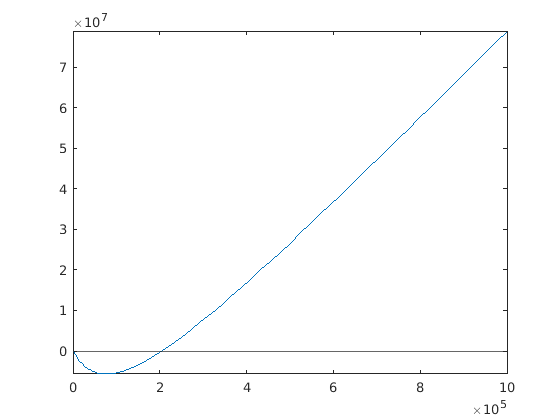

fplot(func,[0,1e6])
yline(0)

**2. **Use a numerical method to obtain the corresponding equilibrium values.

sI = vpasolve(func == 0, H_i, 1e6)

$$sI = 204302.00493471415227715150579324$$

sR = subs(H_r, {gamma, mu_h, H_i}, {exp(-Parameters(2,Index)),...
    Parameters(3,Index), sI})

$$sR = 22371218.341091734764179881066486$$

sS = 35181619.0052 - sI - sR

$$sS = 12606098.659173549700715208638658$$

## Vector-borne disease CHIMERA model

% syms H_s H_i H_r N_h M_s M_i N_m A
% syms  mu_h z_h gamma z_m mu_m gamma C r
% 
% assume(N >= 1)
% assume(H_s>1)
% assume(H_i>=0)
% assume(H_r>=0)
% assume(M_s>1)
% assume(M_i>=0)
% 
% assume(z_h >= 1)
% assume(z_m >= 1)
% assume(mu_h > 0)
% assumeAlso(mu_h < 1)
% assume(mu_m > 0)
% assume(gamma > 0)
% assume(C > 1)
% assume(r > 1)
% 
% N_H = H_s + H_i + H_r;
% N_M = M_s + M_i;

% exponent = z_m * M_i * (H_s/N_H);
% Phi = 1 - ((H_s - 1)/H_s) ^ exponent; 
% 
% Psi = 1 - ((N_H - H_i)/N_H) ^ z_h;
% 
% A = r * N_M* exp( (1 - N_M/C));
% 
% % Susceptible
% f1 = H_s * (1 - Phi) * (1 - mu_h) + N_h * mu_h;
% % Infected
% f2 = H_s * Phi * (1 - mu_h) + H_i * (1 - exp( - gamma)) * (1 - mu_h);
% % Recovered
% f3 = H_r * (1 - mu_h) + H_i * exp( - gamma) * (1 - mu_h);    
% % Susceptible
% f4 = M_s * (1 - Psi) * (1 - exp( - mu_m)) + A;
% % Infected
% f5 = M_s * P_h * (1 - exp( - mu_m)) + M_i * (1 - exp(- mu_m));

Definición de las ecuaciones que presenta organismos infecciosos

% syms H_s H_i H_r M_s M_i N_H
% syms mu_h mu_m gamma r C z_h z_m

1. Humanos susceptibles junto a sus respectivos parámetros y expresiones

% % N_H = H_s + H_i + H_r;
% phi_m = ((H_s - 1)/H_s) ^ (z_m * M_i * (H_s/N_H));
% 
% f1 = H_s * (1 - phi_m) * (1 - mu_h);
% t1 = H_i * (1 - gamma) * (1 - mu_h);

2. Mosquitos susceptibles junto a sus respectivos parámetros y expresiones 

% N_M = M_s + M_i;
% 
% Psi_h = ((N_H - H_i)/N_H)^z_h;
% 
% f2 = M_s * (1 - Psi_h) * (1 - mu_m);
% t2 = M_i * (1 - mu_m );

% F = [f1, f2];
% T = [t1, t2];
% vars = [H_i, M_i];

Jacobiano de la matriz de la siguiente generación

% % JF = jacobian(F, vars);
% % JT = jacobian(T, vars);
% 
% JF = [diff(f1,H_i) diff(f1,M_i); diff(f2,H_i) diff(f2,M_i)]
% JT = [diff(t1,H_i) 0; 0 diff(t2,M_i)]
% % JT = [diff(t1, H_i), 0 ;
% %       0, diff(t2,M_i)  ] ;
% %   expre = JT+JF
% 

**Definición del **$R_T$

% expression = JF/(eye(2) - JT)
% EigenValues = eig(expression);
% 
% R_t = EigenValues(1)

**Definición del **$R_0$

% H_i=0;
% H_r=0;
% 
% N_H = H_s + H_i + H_r;
% M_i = 0;
% N_M = M_s + M_i;
% 
% J_Eval_F = subs(JF, {"H_i", "M_i", "H_s", "M_s","N_H" }, {0, 0, N_H, N_M, N_H});
% J_Eval_T = subs(JT, {"H_i", "M_i", "H_s", "M_s", "N_H"}, {0, 0, N_H, N_M, N_H});
% 
% MultiFT = J_Eval_F/(eye(2) - J_Eval_T);
% EigenValues = eig(MultiFT);
% R_0 = simplify(EigenValues(1))
% 
% 